Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 10**

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining discrete time Inverse Fourier Transform
dtift = @(Xw, w, n) (Xw * exp(1j .* (w' * n))) ./ length(w);

% defining range of analog frequencies
W = logspace(0, 3);

% defining range of digital frequencies
w = linspace(-pi, pi, 1000);
omega_labels = ["-\pi", "-3\pi/4", "-\pi/2", "-\pi/4", 0,...
    "\pi/4", "\pi/2", "3\pi/4", "\pi"];

Q1:

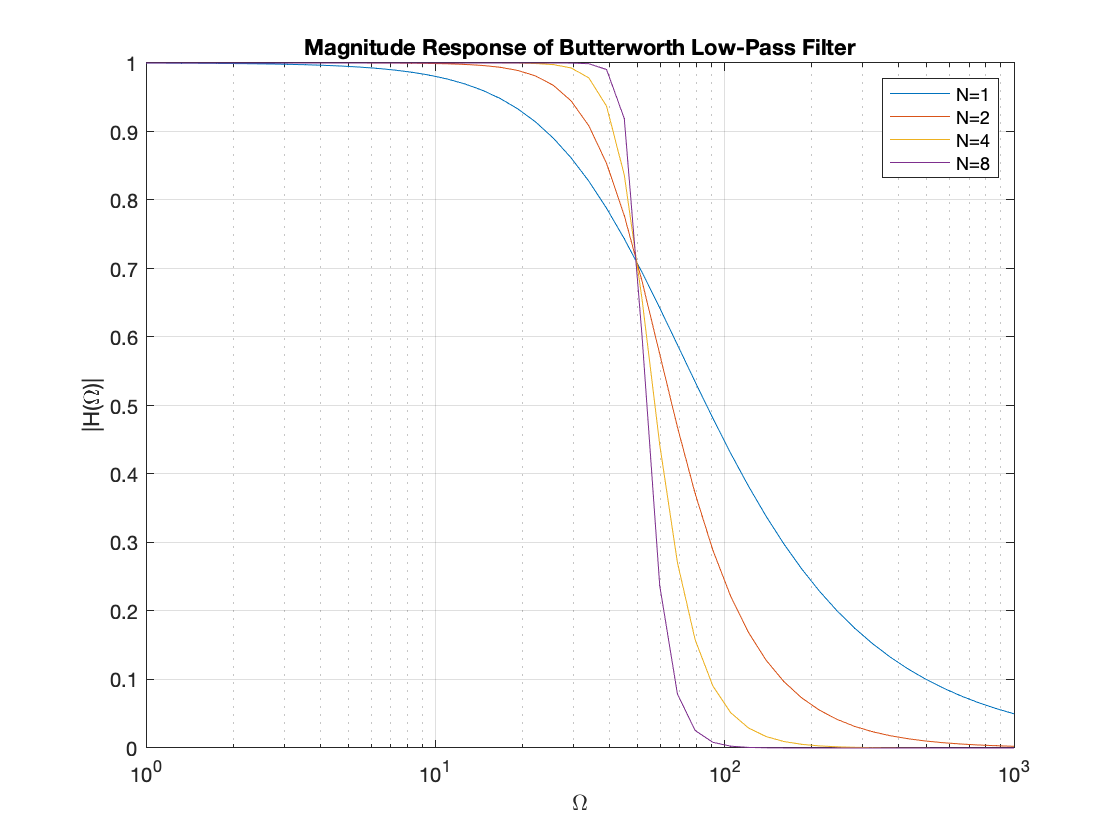

% (a)
Wc = 50;
% order of the filter
N_values = [1, 2, 4, 8];
% Butterworth filter transfer function magnitude
butterworth = @(N, W_c, W) 1 ./ sqrt(1 + (W/W_c).^(2*N));
% Butterworth polynomial roots
butterworth_roots = @(N, W_c) ...
    W_c .* exp(1j .* pi .* (2.*(1:N) + N - 1) ./ (2*N));
% Butterworth filter trnsfer function expression
syms s;
butterworth_tf = @(N, W_c) (W_c ^ N) / ...
    prod(s.*ones(1, N) - butterworth_roots(N, W_c));

% Plot the magnitude response of the filter
figure;
for N = N_values
   semilogx(W, abs(butterworth(N, Wc, W)));
   hold on;
end
title('Magnitude Response of Butterworth Low-Pass Filter');
xlabel('\Omega');
ylabel('|H(\Omega)|');
grid on;
legend('N=1', 'N=2', 'N=4', 'N=8');
hold off;

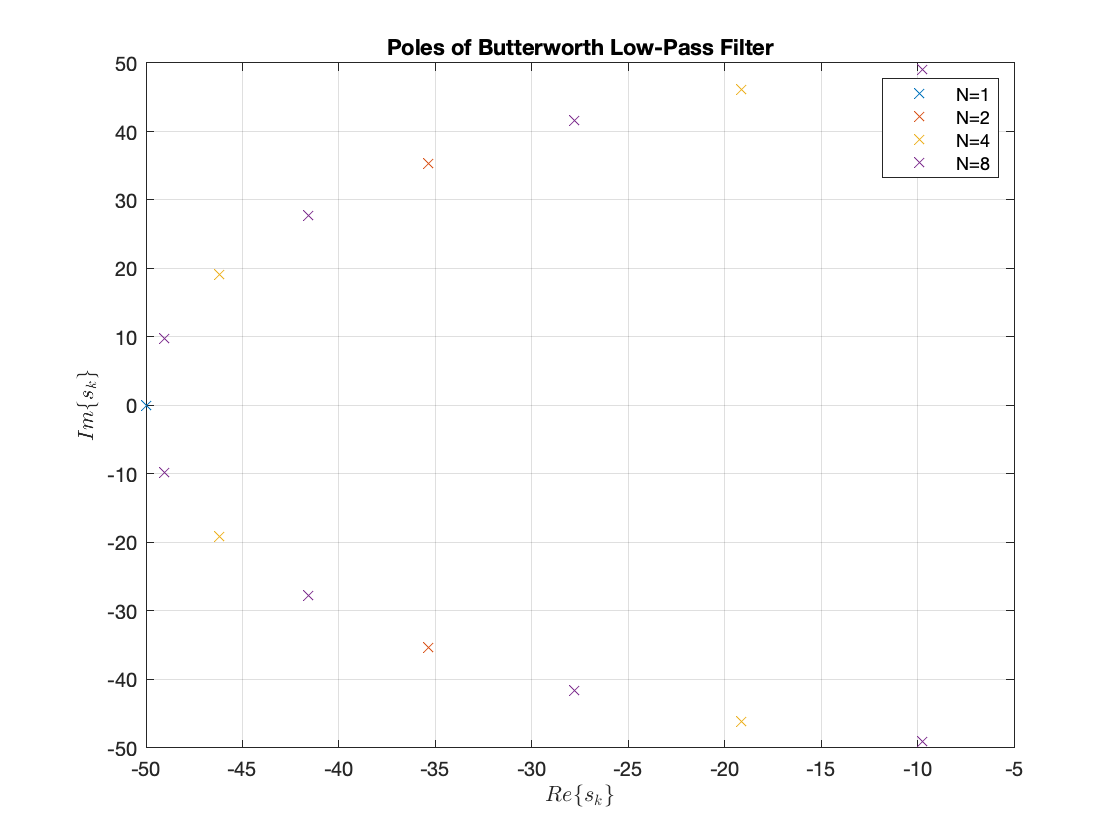

% (b)
% Plot the poles
figure;
for N = N_values
    bw_roots = butterworth_roots(N, Wc);
    plot(real(bw_roots), imag(bw_roots), 'x');
    hold on;
end
title('Poles of Butterworth Low-Pass Filter');
xlabel('$Re\{s_k\}$', "Interpreter","latex");
ylabel('$Im\{s_k\}$', "Interpreter","latex");
grid on;
legend('N=1', 'N=2', 'N=4', 'N=8');
hold off;

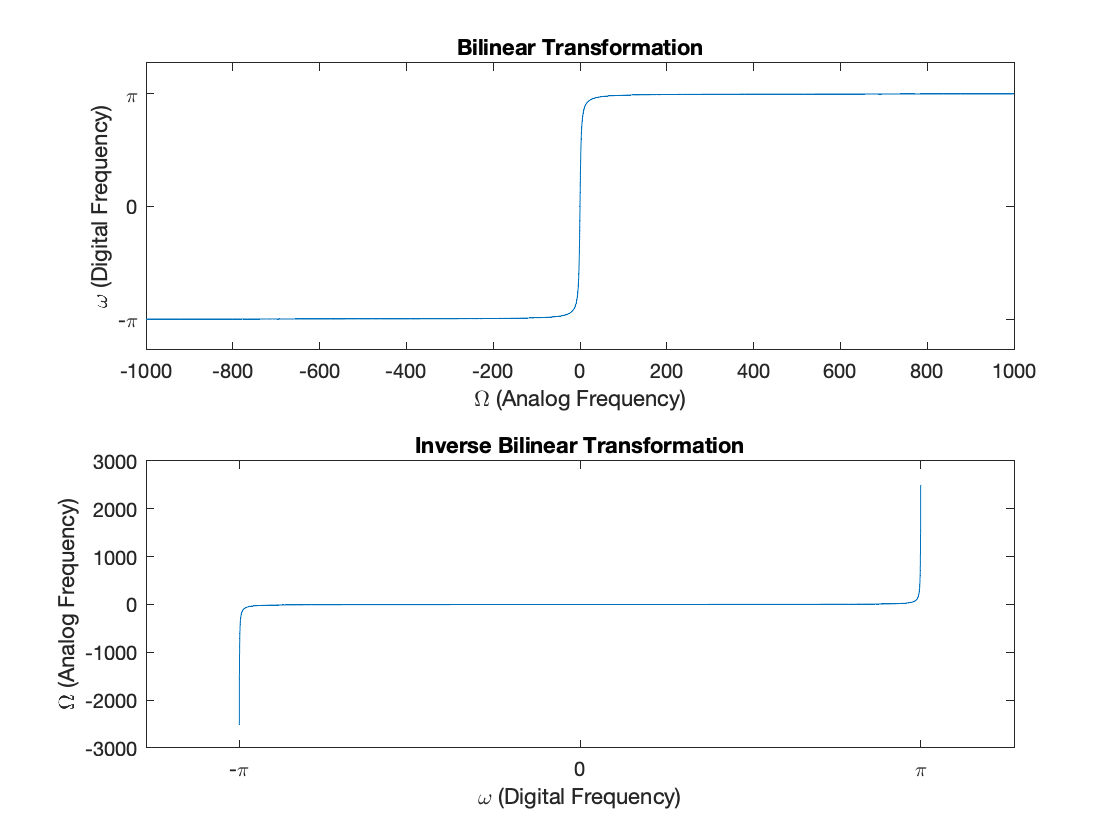

% (c)
T = 1;

% Bilinear Transformation
W = -10^3:0.1:10^3;
w_digital = @(W) 2 .* atan(W .* T ./ 2);
subplot(2,1,1);
plot(W, w_digital(W));
title('Bilinear Transformation');
xlabel('\Omega (Analog Frequency)');
ylabel('\omega (Digital Frequency)');
yticks(-pi:pi:pi); yticklabels(["-\pi", 0, "\pi"]);

% Inverse Bilinear Transformation
xrange = -3.14:0.001:3.14;
w_analog = @(w) (2 / T) * tan(w ./ 2);
subplot(2,1,2);
plot(xrange, w_analog(xrange));
title('Inverse Bilinear Transformation');
xlabel('\omega (Digital Frequency)');
ylabel('\Omega (Analog Frequency)');
xticks(-pi:pi:pi); xticklabels(["-\pi", 0, "\pi"]);

Q2:

% (a)
% Filter specifications
fs = 20 * 1e3;   % Sampling frequency
f1 = 1 * 1e3;    % Passband frequency
f2 = 5 * 1e3;    % Stopband frequency
Rp = -1;         % Passband ripple (dB)
Rs = -40;        % Stopband attenuation (dB)

% Calculating the filter paramenters from the specifications
T = 1 / fs;                 % Time period of sampling
wp = 2 * pi * (f1/fs);      % Normalised Passband frequency
ws = 2 * pi * (f2/fs);      % Normalised Stopband frequency
Wp = (2/T) * tan(wp/2);     % Analog Passband Frequency
Ws = (2/T) * tan(ws/2);     % Analog Stopband Frequency
delta_p = 10 ^ (Rp / 20);   
delta_s = 10 ^ (Rs / 20);

% Calculating the filter order
N = ceil(log(sqrt((delta_s^(-2) - 1)/(delta_p^(-2) - 1)))/log(Ws/Wp));
display(N);

N = 3

% Calculating the cutoff frequency
Wc1 = Wp / (delta_p^(-2) - 1)^(1/(2*N));
Wc2 = Ws / (delta_s^(-2) - 1)^(1/(2*N));
% Since Wc1 <= Wc <= Wc2:
Wc = (Wc1 + Wc2)/2;
display(Wc1); display(Wc); display(Wc2);

Wc1 = 7.9355e+03

Wc = 8.2767e+03

Wc2 = 8.6179e+03

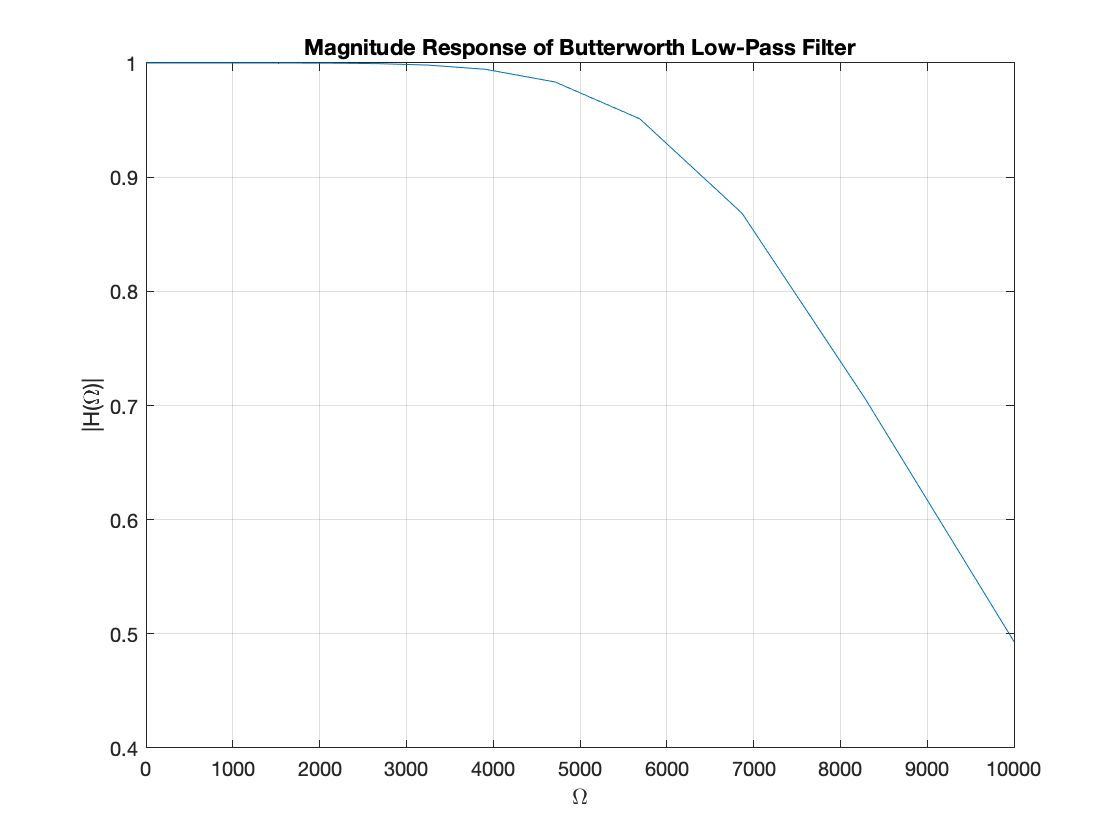

% Display filter transfer function
figure;
W = logspace(0, ceil(log10(Wc)));
Ha = butterworth(N, Wc, W);
plot(W, Ha);
title('Magnitude Response of Butterworth Low-Pass Filter');
xlabel('\Omega');
ylabel('|H(\Omega)|');
grid on;

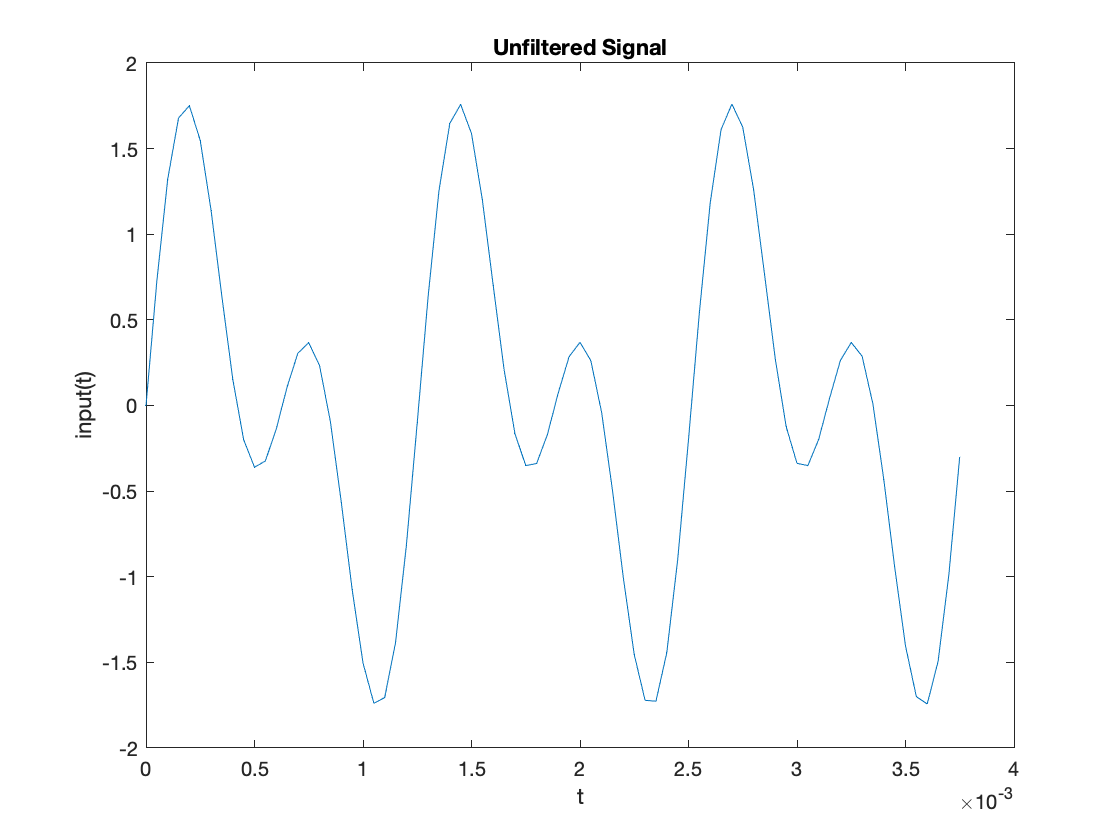

% (b)
t = 0:T:6*pi/5000;
w = -pi:0.001:pi;
% Sinusoids within and out of passband (Wc = 8,276 rad/sec)
x1 = sin(5000 * t);
x2 = sin(10000 * t);
signal_t = x1 + x2;

% Convert to frequency domain
signal_s = dtft(signal_t, t./T, w);
% Multiplication in laplace domain
filter = butterworth(N, Wc, w_analog(w));
filtered_s = signal_s .* filter;
% return to time domain
filtered_t = real(dtift(filtered_s, w, t./T));

% Plot input and output signals
figure;
plot(t, signal_t);
xlabel("t"); ylabel("input(t)"); title("Unfiltered Signal");

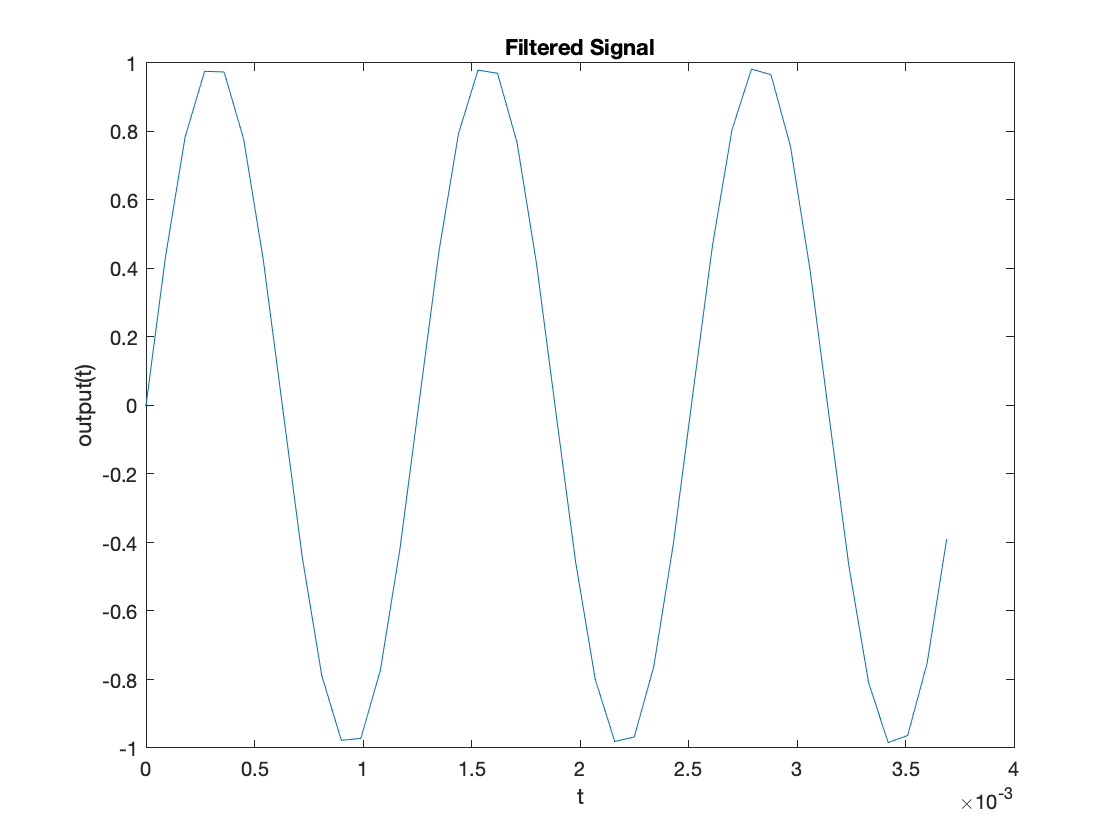

plot(t, filtered_t);
xlabel("t"); ylabel("output(t)"); title("Filtered Signal");